# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';

### Chapter 6: 短期性分析第二种路径（基于时间序列特征的谱系分类）

#### 5.1 构造特征

% 导入数据
country_SA = StatisticsAnalysis('TablePath', path_country);
country = country_SA.Table;
daily_SA = StatisticsAnalysis('TablePath', path_daily, ...
    'ImportOptions', {'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}} ...
    );
daily = daily_SA.Table;
% 每日数据所涉及的国家
daily_location = unique(daily{:,'location'});
daily_location(ismember(daily_location, {'Senegal'})) = [];
size(daily_location)

ans =     20     1


% new_cases; total_cases; new_tests; total_tests; positive_rate;
% new_vaccinations; total_vaccinations; hosp_patients; icu_patients;
% stringency_index
X = zeros(20, 3*6);
TR = timerange('2021-10-01', '2022-01-01');
list = {'new_cases'; 'total_cases'; 'stringency_index'};
MeanValueTable = table2timetable(daily_SA.WholeTable);
MeanValueTableTR = MeanValueTable(TR,:);
MeanValueTable = MeanValueTable(1,:);
MeanValueTable = removevars(timetable2table(MeanValueTable), {'location', 'continent', 'date'});
for vn_idx = MeanValueTable.Properties.VariableNames
    vn = vn_idx{1};
    MeanValueTable{1, vn} = tsnanmean(MeanValueTableTR{:, vn});
end
MVO = {
    {'new_cases', 'total_cases'}, 'Increment-Addition', {'InterpolationStyle', 'spline'};
    {'new_tests', 'total_tests'}, 'Increment-Addition', {'InterpolationStyle', 'spline'};
    %'positive_rate', 'Interpolation', {'InterpolationStyle', 'spline', 'ConstantValues', MeanValueTable{1,'positive_rate'}};
    {'new_vaccinations', 'total_vaccinations'}, 'Increment-Addition', {'InterpolationStyle', 'spline'};
    %'hosp_patients', 'Interpolation', {'InterpolationStyle', 'spline', 'ConstantValues', MeanValueTable{1,'hosp_patients'}};
    %'icu_patients', 'Interpolation', {'InterpolationStyle', 'spline', 'ConstantValues', MeanValueTable{1,'icu_patients'}};
    %'stringency_index', 'Interpolation', {'InterpolationStyle', 'spline', 'ConstantValues', MeanValueTable{1,'stringency_index'}}
    };

for idx1 = 1: 20
    thisCountry = daily_location{idx1};
    country = country_SA.Update('SelectTableOptions', {'location', thisCountry}).Table;
    thisPopulation = country{:, 'population'};
    thisDaily = daily_SA.Update('SelectTableOptions', {'location', thisCountry}).Table;
    for idx2 = 1: 3
        thisVar = list{idx2};
        MissingMap = ismissing(thisDaily{:,thisVar});
        thisDaily{MissingMap,thisVar} = MeanValueTable{1,thisVar};
        X(idx1, (idx2-1)*6+1) = (tsnanmax(thisDaily{:,thisVar}) - tsnanmin(thisDaily{:,thisVar})) / thisPopulation;
        X(idx1, (idx2-1)*6+2) = tsnanstd(thisDaily{:,thisVar}) / thisPopulation;
        X(idx1, (idx2-1)*6+3) = tsnanmean(thisDaily{:,thisVar}) / thisPopulation;
        X(idx1, (idx2-1)*6+4) = skewness(thisDaily{:,thisVar});
        X(idx1, (idx2-1)*6+5) = kurtosis(thisDaily{:,thisVar});
        if any(ismissing(thisDaily{:,thisVar}))
            X(idx1, (idx2-1)*6+6) = NaN;
        else
            thisAutoCor = autocorr(thisDaily{:,thisVar}, 8, 3);
            X(idx1, (idx2-1)*6+6) = tsnanmean(thisAutoCor(1:8));
        end
    end
end

sum(sum(ismissing(X)))

ans =      0

#### 5.2 谱系分类

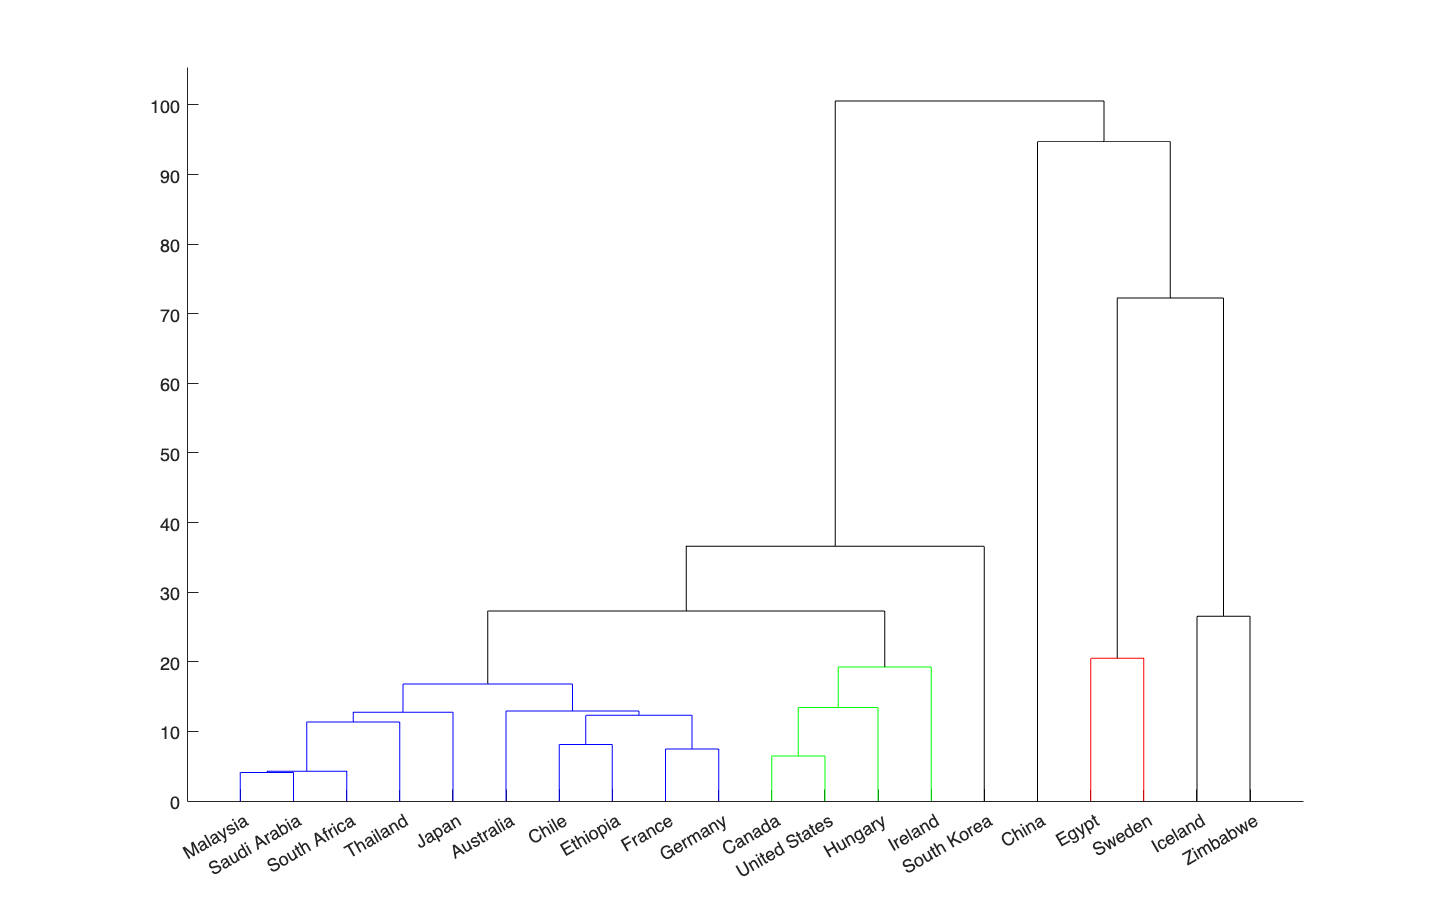

Y = pdist(X);
Y = squareform(Y);
Z = linkage(Y);
dendrogram(Z, 'Labels', daily_location, 'ColorThreshold', 25);

plot(daily_SA.Update('SelectTableOptions', {'location', Malaysia, 'date', TR}).Table)